syms t k;
T = 2 * pi;
T1 = 0.5 * pi;
omega = 2 * pi / T;
t0 = -T/2;
x = heaviside(t + T1) - 2 * heaviside(t - T1) - heaviside(-t - T1); 
a = 1/T * int(x * exp(-1j * k * omega * t), t, [t0, t0 + T]);

for k1 = -5 : -1
    aneg_k(-k1) = subs(a, k, k1);
end

for k1 = 1 : 5
    apos_k(k1) = subs(a, k, k1);
end

s1 = apos_k(1) * exp(j*t) + aneg_k(1) * exp(-j*t);
s2 = apos_k(2) * exp(j*2*t) + aneg_k(2) * exp(-j*2*t);
s3 = apos_k(3) * exp(j*3*t) + aneg_k(3) * exp(-j*3*t);
s4 = apos_k(4) * exp(j*4*t) + aneg_k(4) * exp(-j*4*t);
s5 = apos_k(5) * exp(j*5*t) + aneg_k(5) * exp(-j*5*t);

s_sum = s1 + s2 + s3 + s4 + s5;

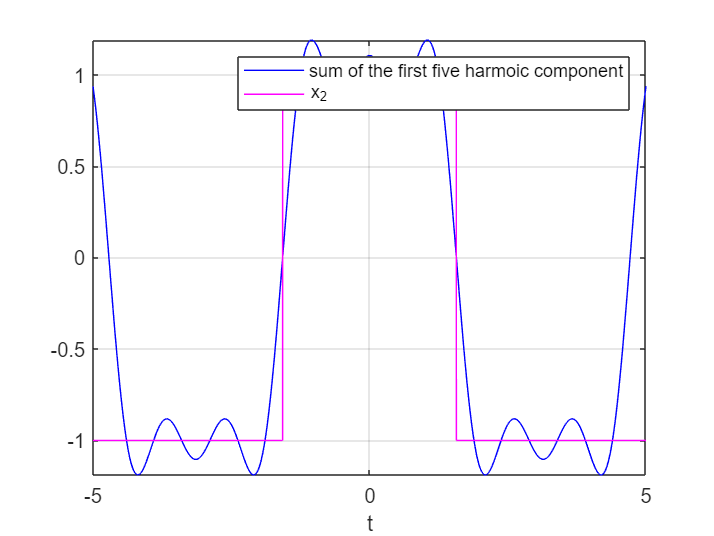

p1 = fplot(s_sum);
p1.Color = "b";
hold on;

p2 = fplot(x);
p2.Color = "m";

% axis([- pi, pi, -1, 1]);
legend([p1, p2],{'sum of the first five harmoic component',"x_2"});
xlabel("t");
grid on;